clear; 
s0_add_paths;

# Create the image features

nOri = 8; nSurroundOrient = 8;
nCentOrient = 2;
orientations = linspace(0, pi, nOri+1);
orientations = orientations(1:end-1);
surrOrient = orientations;
centOrient  = orientations(1:nCentOrient); 

numpix  = 400;
fovs    = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
fov     = fovs(1);
pixperdeg = numpix / fov;
filter_cpd = 3;
ppc     = round(pixperdeg./ filter_cpd); % pixels per cycle
support = 6;
filtersize = ppc .* support; 

num     = numpix; 
surroundSize = round(pixperdeg * 10);
centerSize = round(pixperdeg * 3);
picMask = gen_disk(num, surroundSize, 1);
gapMask = abs(gen_disk(num, centerSize + round(0.2 * pixperdeg), 1) -1); % Adds a small gap between center and surround
cenMask = gen_disk(num, centerSize, 1);


### The stimuli with surround suppression

Images vary across 8 surround orientations and 4 center orientations

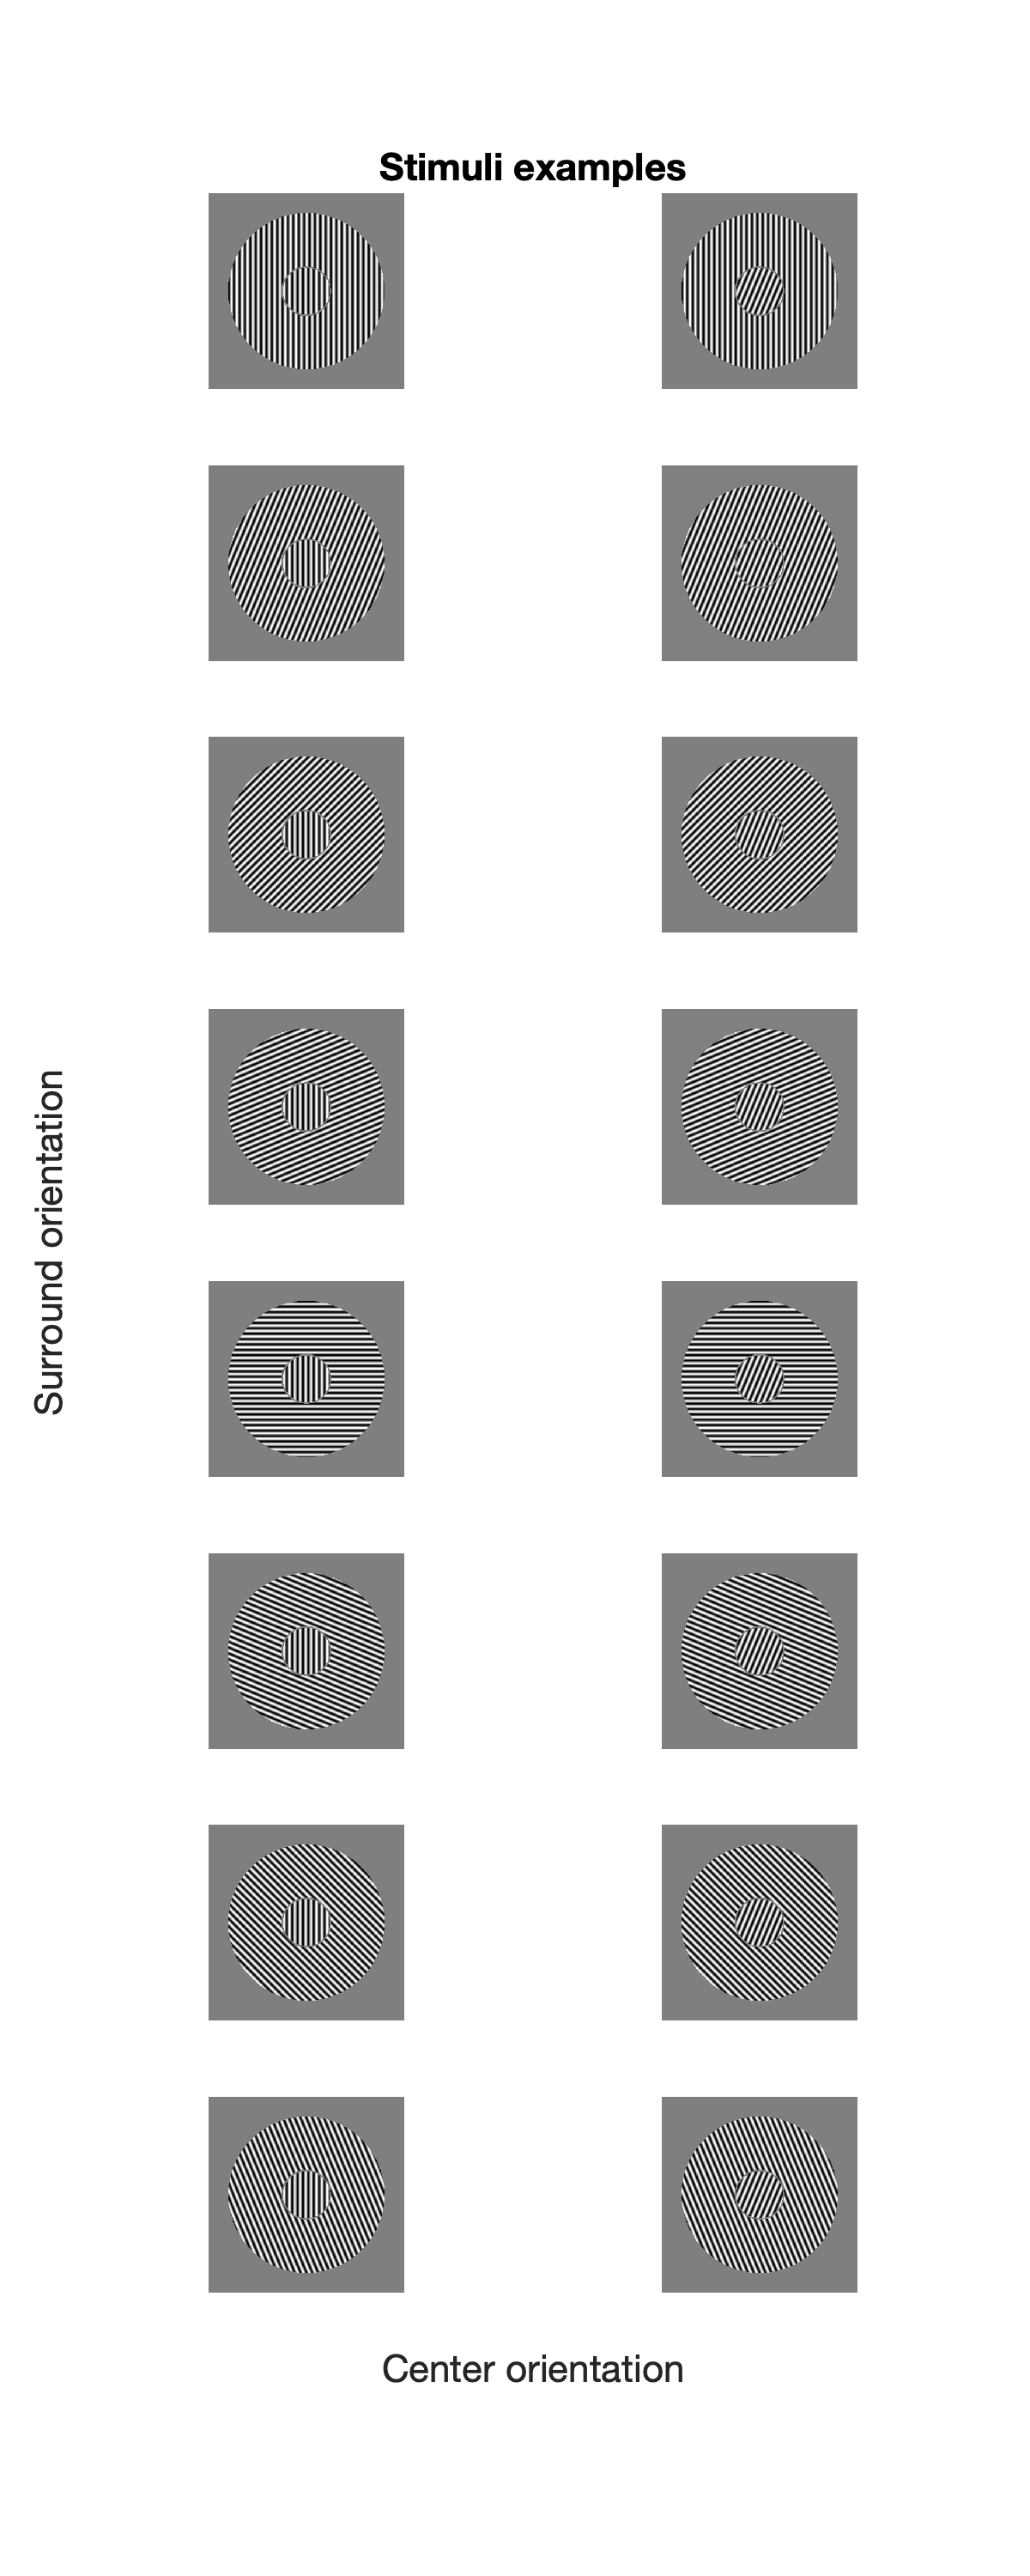

tune_stim = cell(nCentOrient, 1);
surr_stim = cell(nSurroundOrient, nCentOrient);
[x, y]  = meshgrid((0:num- 1)/ppc);

% Define phase shift for surround
phaseshift = pi/4;

for i = 1:nSurroundOrient
    for j = 1:nCentOrient
        % Center
        theta = centOrient(j);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        center = 0.5*(cenMask.*real(h));
        
        % Surround
        theta = surrOrient(i);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y + phaseshift)*pi*2);
        h = real(h);
        surr = 0.5*(picMask.*h.*(1-cenMask));
        
        surr_stim{i, j} = (surr .* gapMask)+ center;
        
    end
end

fig = figure('Renderer', 'painters', 'Position', [10 10 300*nCentOrient 1500], 'Color', [1 1 1]);
for i = 1:nCentOrient 
    for j = 1:nSurroundOrient
        subplot(nSurroundOrient, nCentOrient, (j-1)*nCentOrient+i)
        imshow(surr_stim{j, i}, [])
        n = size(surr_stim{j, i}, 1);
%         title(sprintf('%d x %d', n, n))
    end
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel(han,'Center orientation');
ylabel(han,'Surround orientation');
title(han,'Stimuli examples');

## Stimuli used to create tuning curve

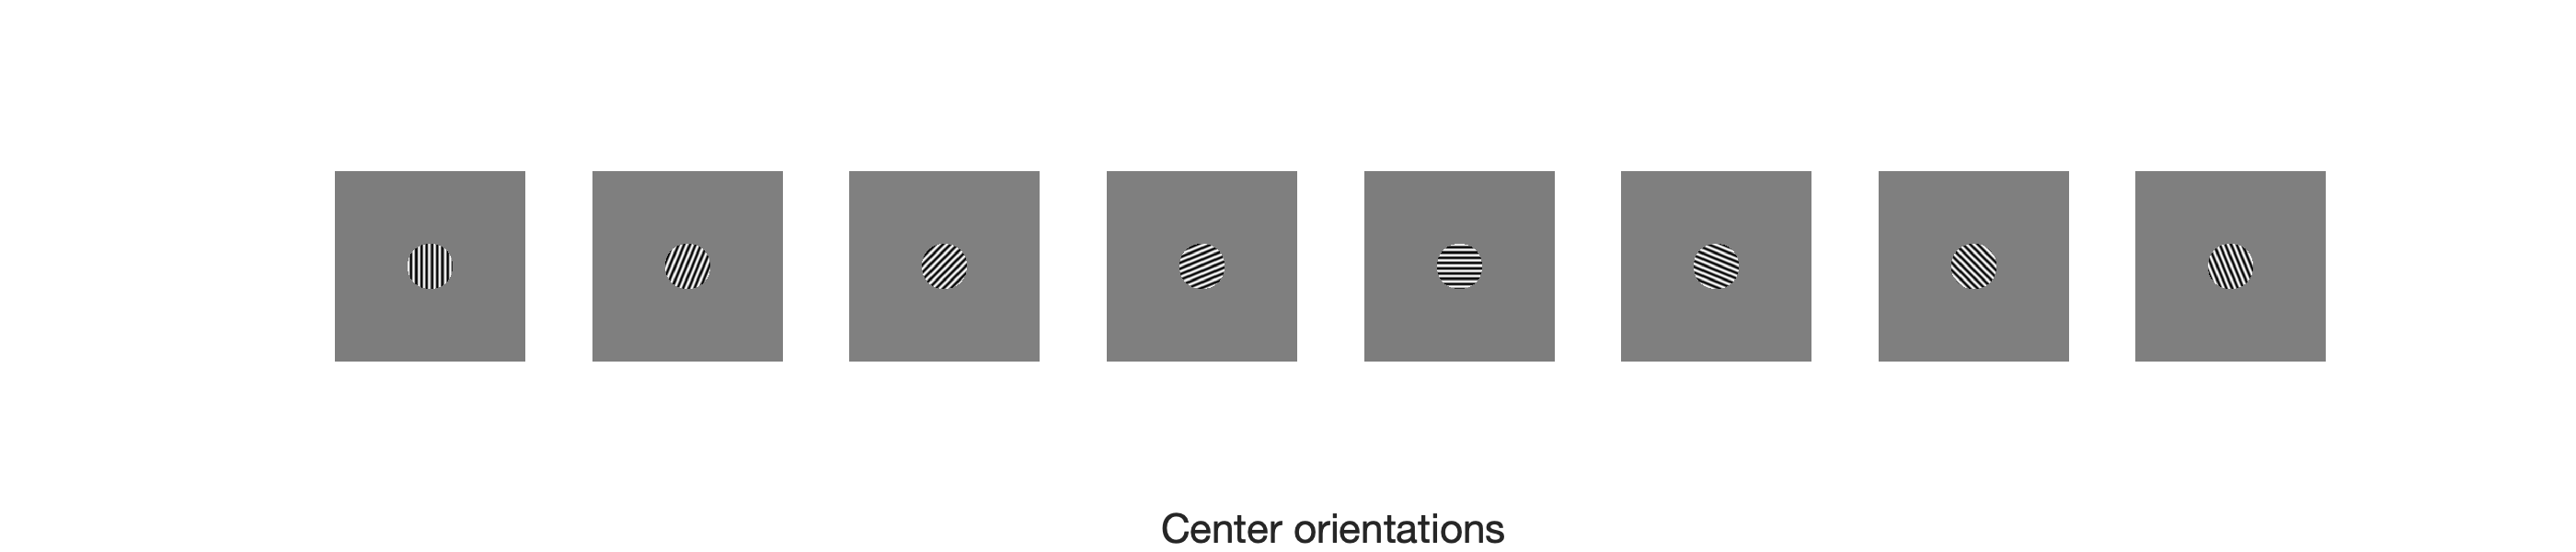

tune_stim = cell(nCentOrient, 1);
for i = 1:nOri
    [x, y]  = meshgrid((0:num- 1)/ppc);
    theta = orientations(i);
    wave_c = cos(theta);
    wave_s = sin(theta);
    h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
    tune_stim{i,1} = .5*(cenMask.*real(h));
end

fig = figure('Renderer', 'painters', 'Position', [10 1200 1400 300]);
for i = 1:nOri
    subplot(1, nOri, i)
    imshow(tune_stim{i, 1}, [])
    n = size(tune_stim{i, 1}, 1);
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.XLabel.Visible='on';
xlabel(han,'Center orientations');

# Frame the problem

### Energy extraction

#### 
$$E(x,y,\theta) = \sum_{\phi}\left(I(x, y)F(x,y,\theta, \phi)\right)^2$$


#### * $I$ the image

#### * $F$ the filter (the neuron)

#### * $x,\;y$ indicates the neuron's location

#### * $x^{\prime } ,y^{\prime } \;$is the neuron's receptive field

#### * $\theta \;$ neuron's preferred orientation

#### * $\phi \;$ the phases, sine or cosine

### Get the filters (Neurons)

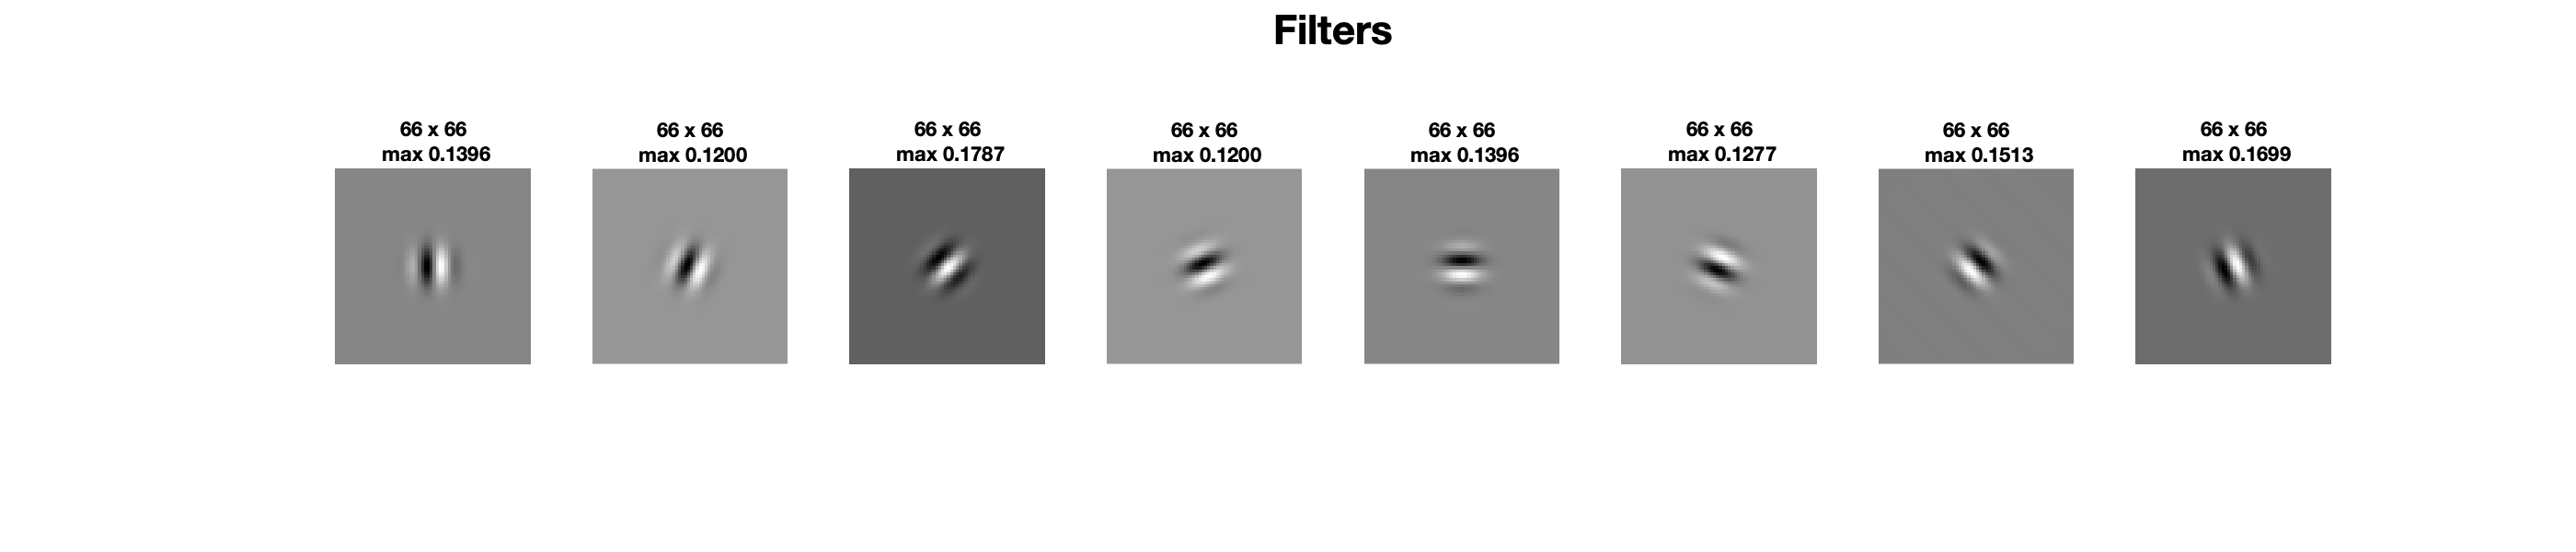

% extract contrast energy
% create filters

% Broaden the orientation bandwidth of the filters by restricting the gaussian mask sigma 
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 300]);
[Gabor_c, Gabor_s] = makeGaborFilter2(ppc, orientations, support, ppc*0.4);
for i = 1:nOri
    subplot(1, nOri, i)
    imshow(Gabor_c{i}, [])
    n = size(Gabor_c{i}, 1);
    title(sprintf('%d x %d\n max %.04f', n, n, max(Gabor_c{i}(:))))
end
han=axes(fig,'visible','off');
han.FontSize = 20;
han.Title.Visible='on';
title(han,'Filters');

### Extract the contrast energy 

% x, y, orient_channnel, surrOri, centOri
tune_E = nan(numpix, numpix, nOri, nOri);
surr_E = nan(numpix, numpix, nOri, nSurroundOrient, nCentOrient);

for i = 1:nOri
    
    tune_E(:, :, :, i) = Icontrast(tune_stim{i, 1}, Gabor_c, Gabor_s);

    for j = 1:nCentOrient
        surr_E(:, :, :, i, j) = Icontrast(surr_stim{i, j}, Gabor_c, Gabor_s);
    end
end

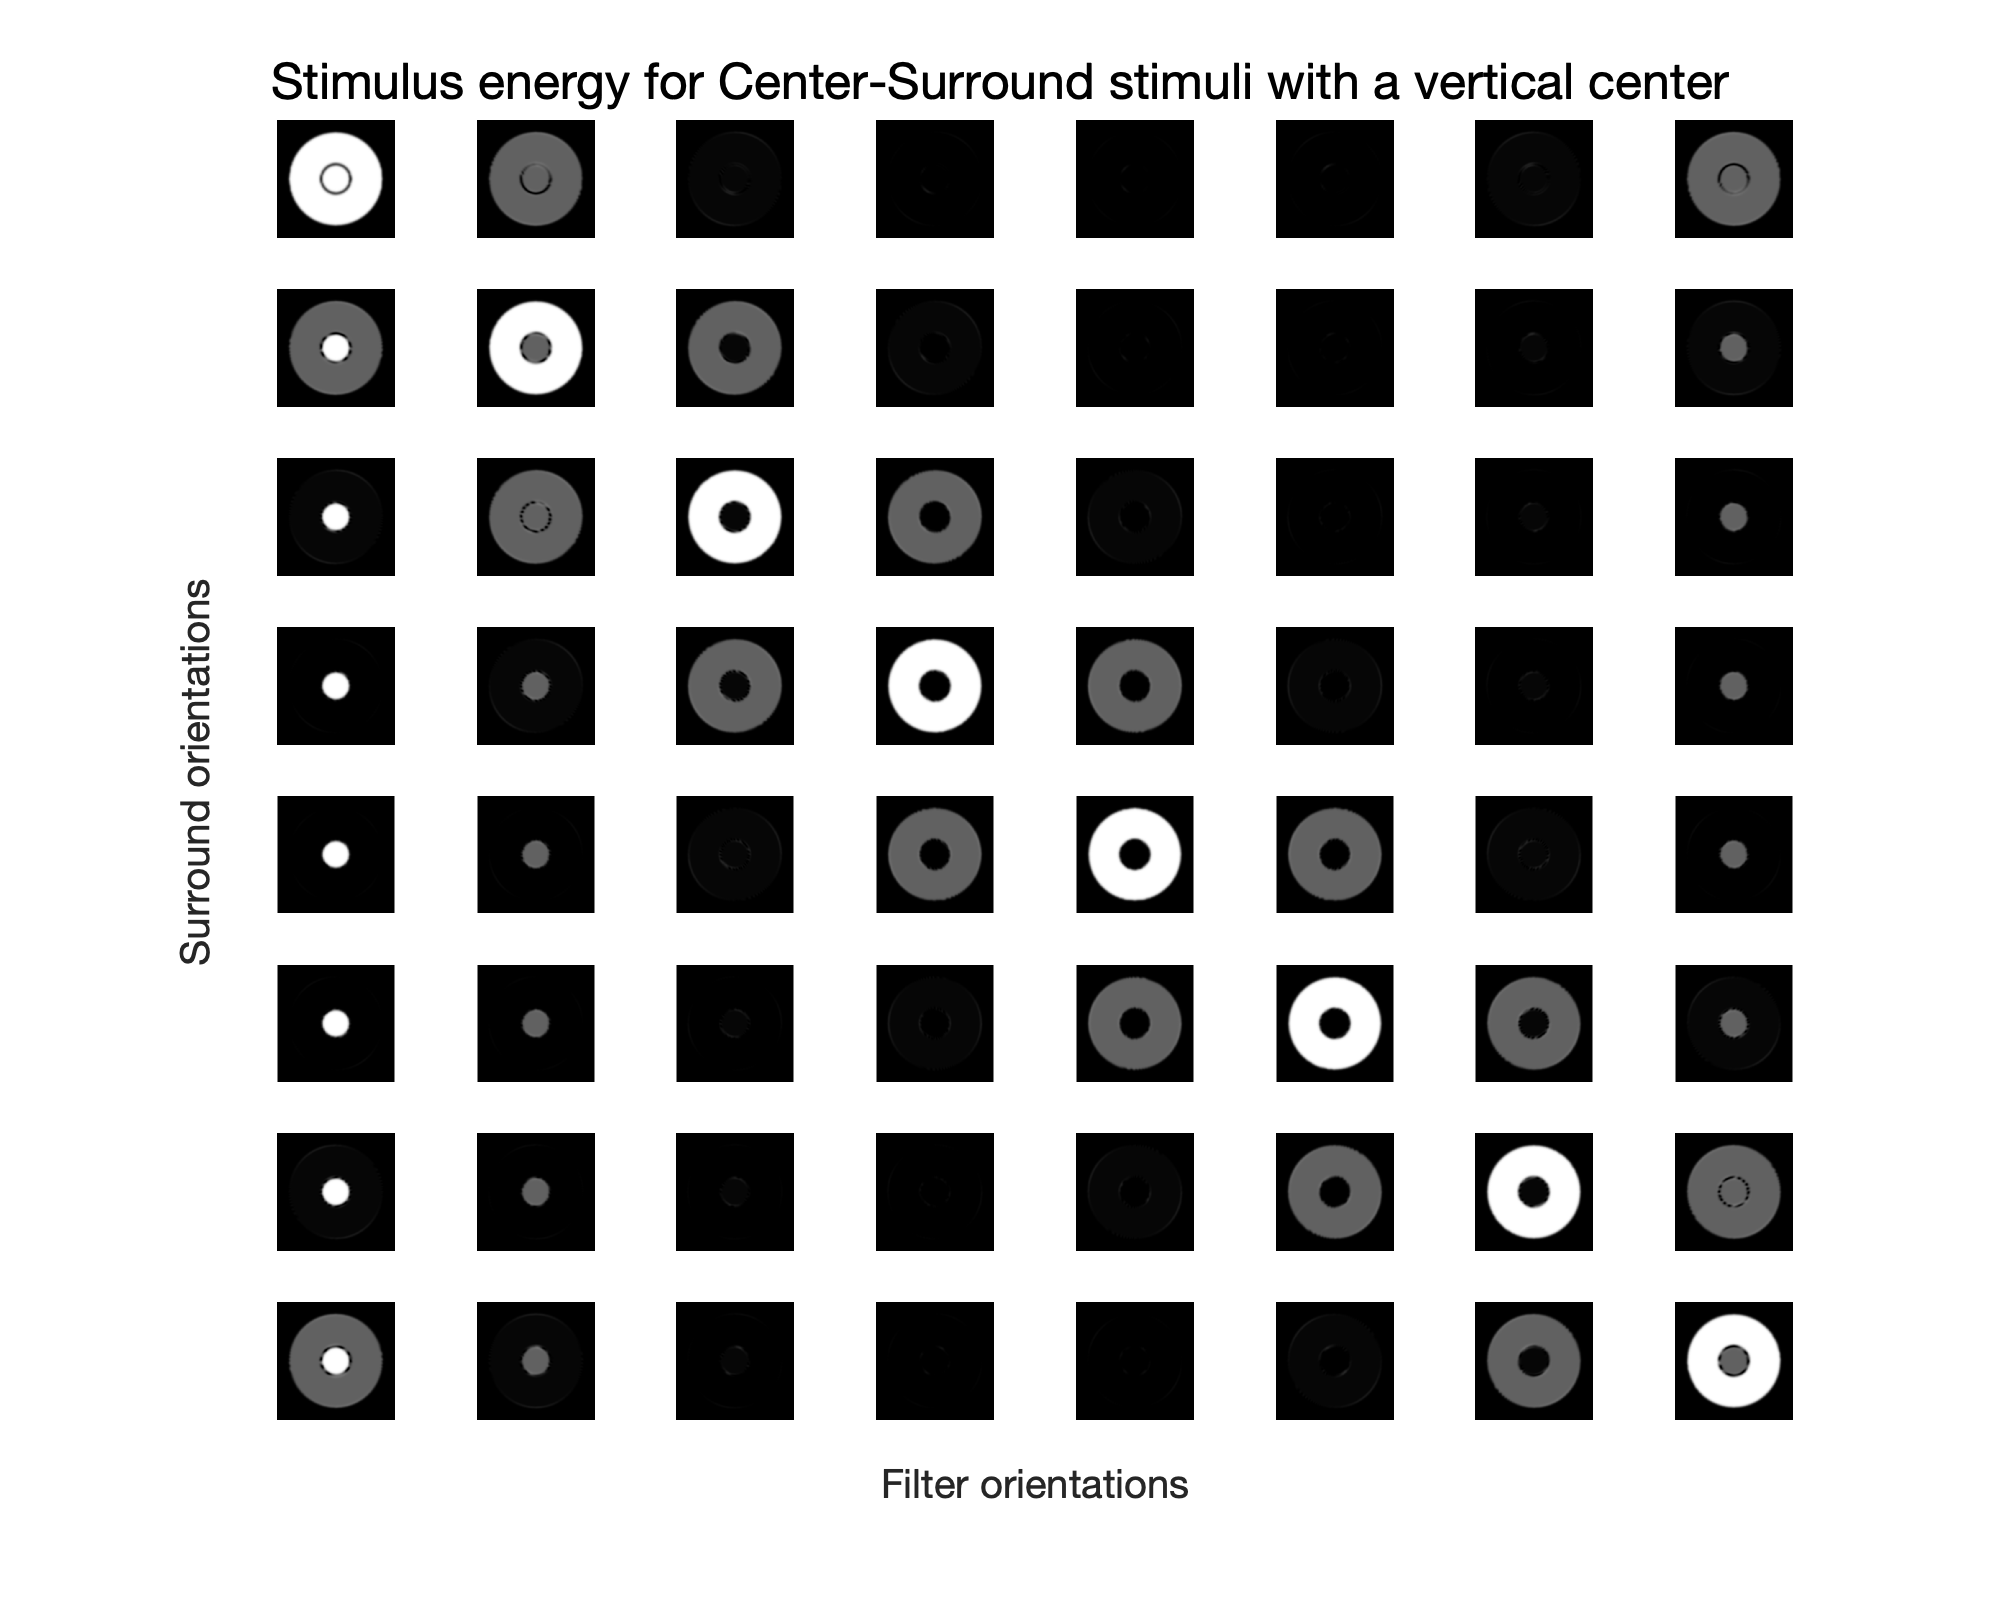

whichCent = 1;
fig = figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
surr_E1 = surr_E(:, :, :, :, :);
maxe = max(surr_E1(:));
mine = min(surr_E1(:));
for j = 1:nSurroundOrient
    for i = 1:nOri
        subplot(nSurroundOrient, nOri, nOri*(j-1)+i)
        tar = surr_E(:,:,i,j,whichCent);
        imshow(tar, [0, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel(han,'Filter orientations','FontSize', 20);
ylabel(han,'Surround orientations','FontSize', 20);
sgtitle('Stimulus energy for Center-Surround stimuli with a vertical center', 'FontSize', 25)

# Calculate the neurons' response at the center 

### The general equation that calculate the response is 

#### 
$$d(\theta^c) = \sum_{x,y\in C} \frac{E(x, y, \theta^c)}{\sigma + Z(x,y,\theta^c)}$$


* $Z$ is the normalization

* $C$ is the center area, see the below figure. 

* $\theta^c$ preferred orientation for neurons at the center

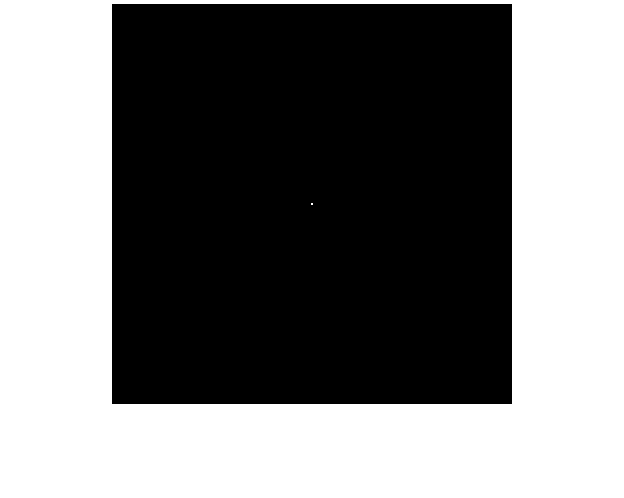

% the center mask: C
figure;
w = gen_disk(numpix, 2, 1);
imshow(w, [])

### The CE model 

The model postulates that the normalization is a constant


$$Z = \text{Const}$$


#### Center surround stimuli:

% example for CE model
whichCent = 1;
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(surr_E(:,:,:,:,:));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Filter orient x surround orient x center orient
r_surrCE = squeeze(s(whichCent,:,:)); 


#### Center stimuli:

params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,whichCent));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (Z + sig);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));
% add exponential
s = d.^alpha;
r_centCE = s; 

#### Get the curves

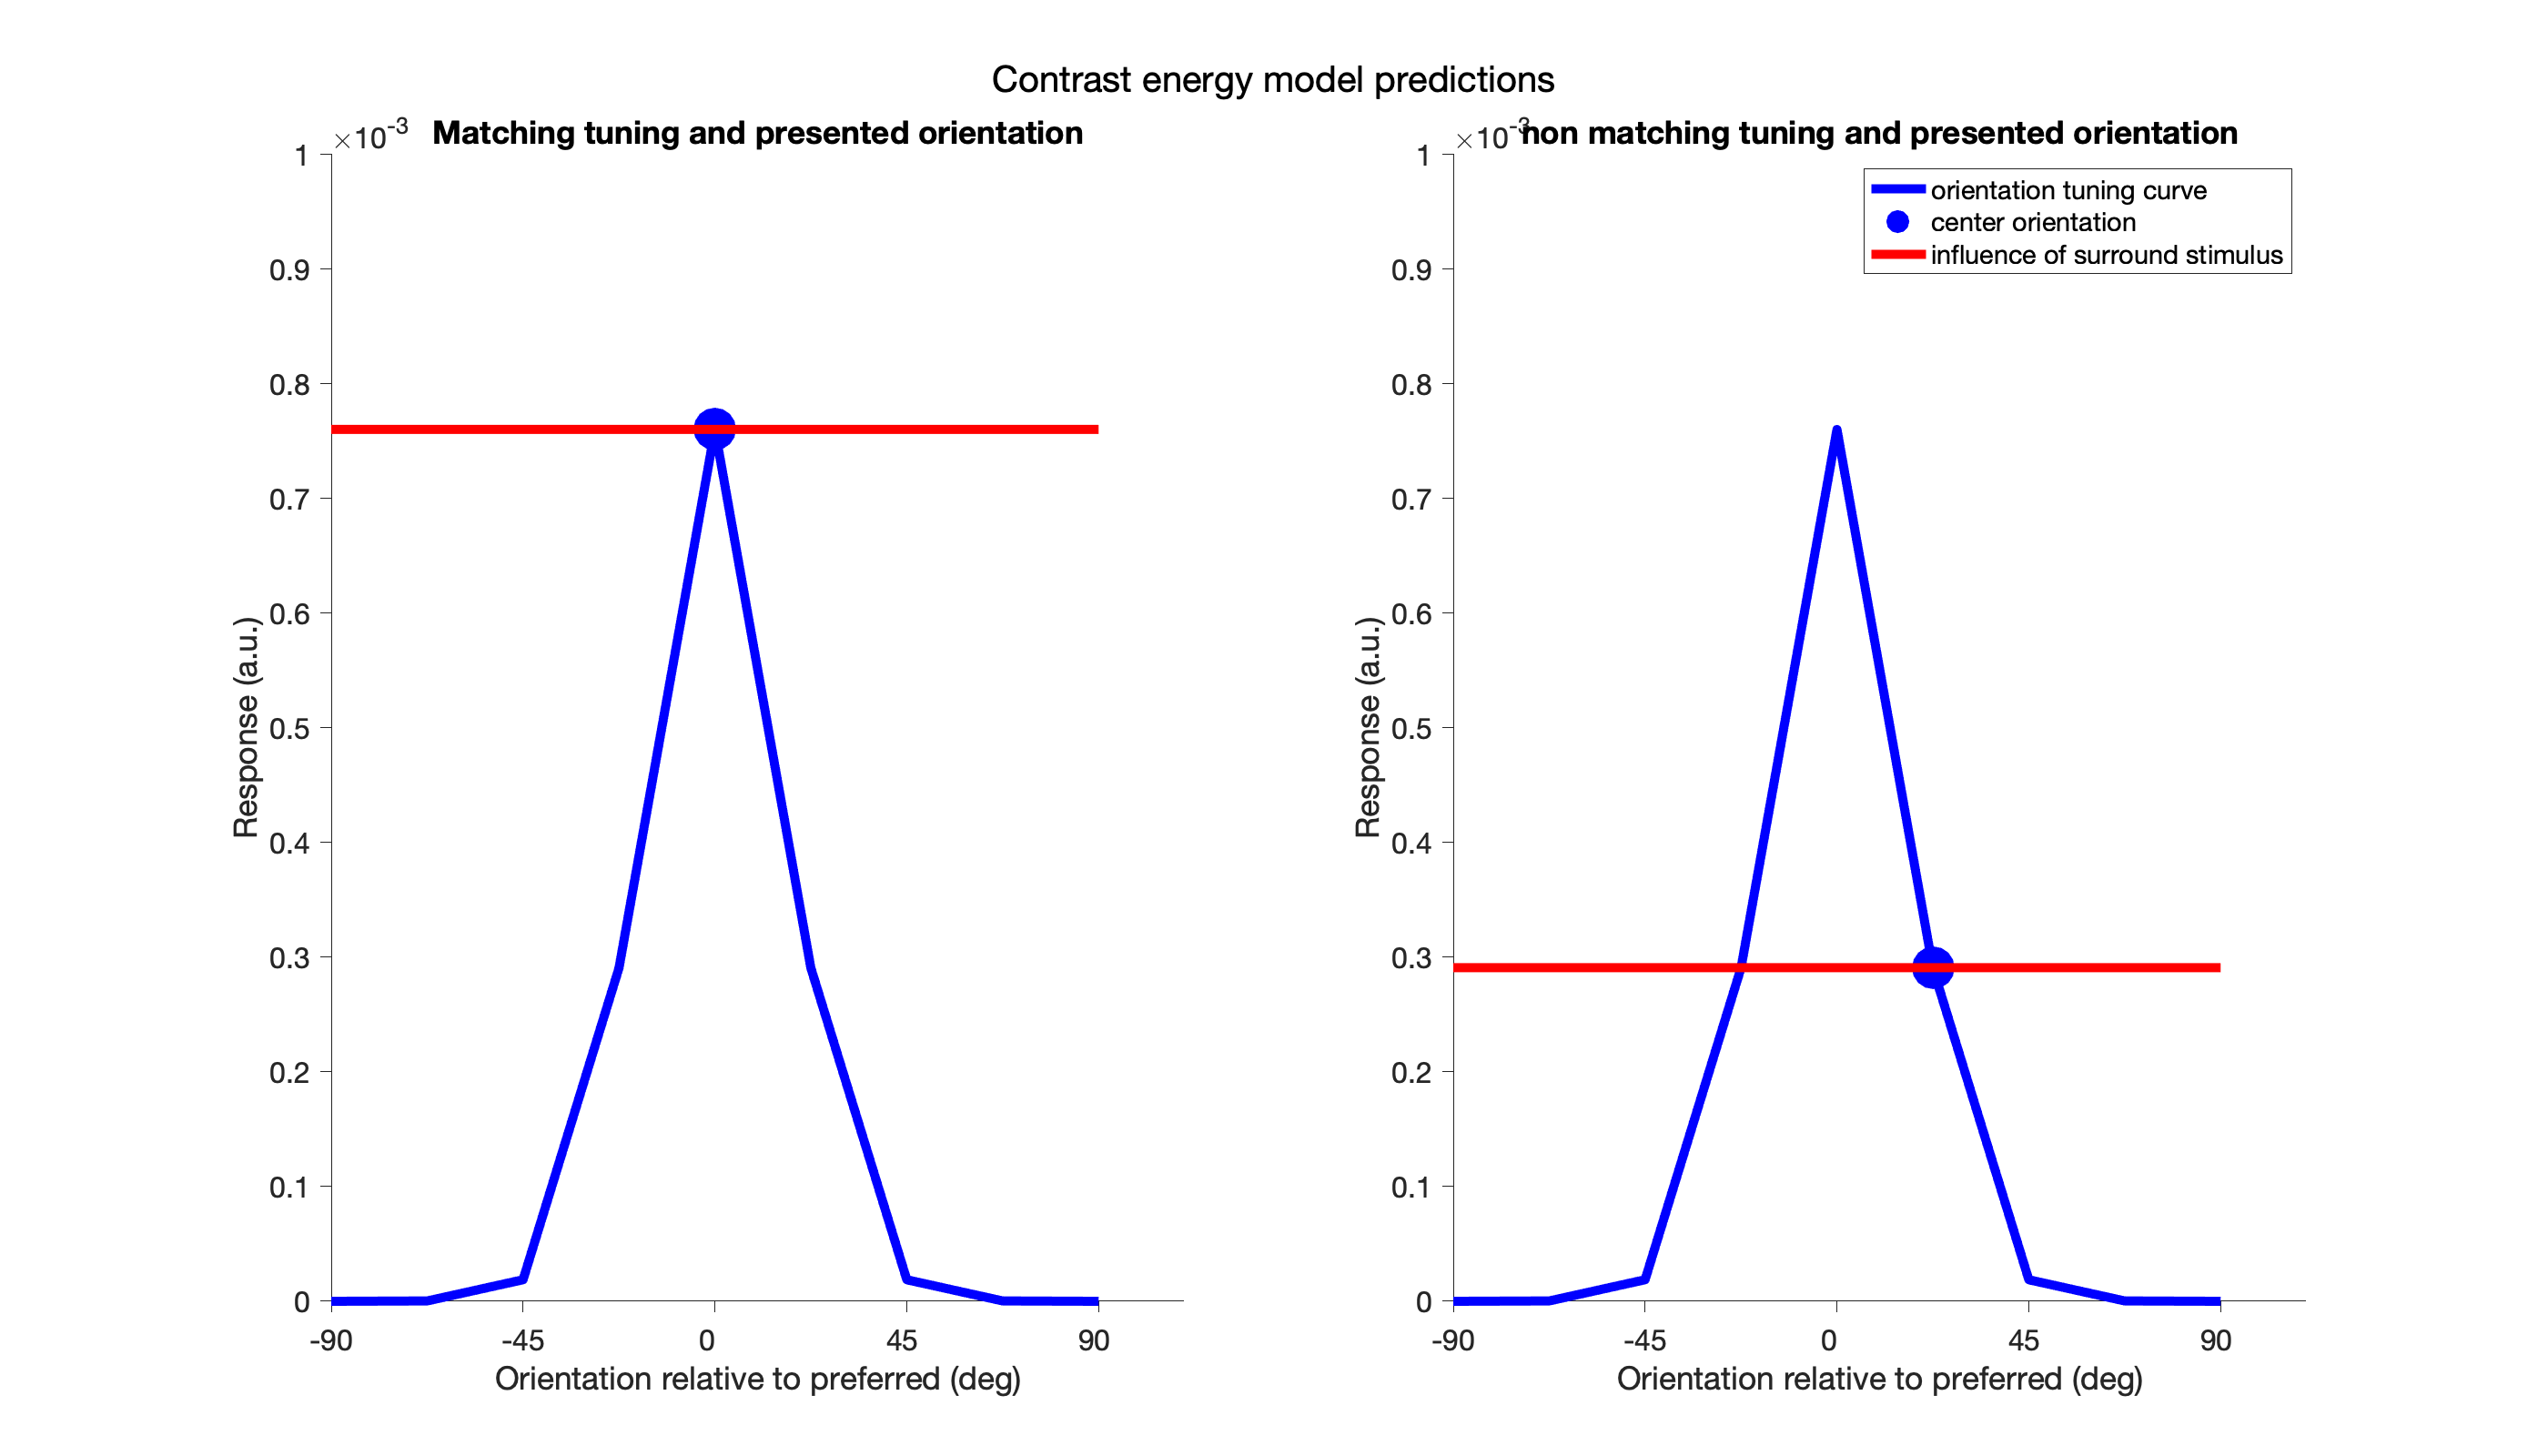

tune_curve      = zeros(nOri, 1);
tune_curve(1:4) = r_centCE(5:8);
tune_curve(5:8) = r_centCE(1:4);

supp_curve      = zeros(nOri, nCentOrient);
supp_curve(1:4,:) = r_surrCE(5:8,:);
supp_curve(5:8,:) = r_surrCE(1:4,:);

tune_curve1 = [tune_curve; tune_curve(1)];
supp_curve1 = [supp_curve; supp_curve(1,:)];

ybounds = [0 ceil(max(supp_curve1(:))*1000)/1000];
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800]);
subplot(1,2,1)
plot(rad2deg([orientations pi]), tune_curve1, 'b', 'LineWidth', 5)
hold on
plot(rad2deg(orientations(5)), tune_curve1(5), 'b.', 'MarkerSize', 80)
plot(rad2deg([orientations pi]), supp_curve1(:,1),'r', 'LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 16, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation')


subplot(1,2,2)
plot(rad2deg([orientations pi]), tune_curve1,'b','LineWidth', 5)
hold on
plot(rad2deg(orientations(6)), tune_curve1(6), 'b.', 'MarkerSize', 80)
plot(rad2deg([orientations pi]), supp_curve1(:,2),'r','LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 16, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation')
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus')

han=axes(fig,'visible','off');
title(han,'Dependence of surround suppression on center orientation','FontSize', 20);
sgtitle('Contrast energy model predictions', 'FontSize', 20)

### The OTS model 

The model postulates that the normalization is a constant


$$Z(\theta) = \sum_{x',y',\theta'} E(x', y', \theta)F(x', y', \theta';\theta)$$


#### A example 

% Compute tuned normalization pool

sig_long  = .8;
sig_short  = .8;
sig_dot = .01;

params = [.1, 1];

sz = filtersize * 3; %round(size(surr_E, 1) / 20)*2;

F = kernel_weight(sig_long, sig_short, sig_dot, sz, 'oriTuned');
Z = NaN(size(surr_E));
r_surround = NaN(nOri,nCentOrient);
for whichCent = 1:nCentOrient

    for ep = 1:nSurroundOrient
        % energy: x, y, neuron orient, center Orient, Surround orient
        E = surr_E(:, :, :, ep, whichCent);
    
        Z_thetas = NaN(size(E));
        
        for theta1 = 1:nOri
            Ztheta1 = 0;
            for theta2 = 1:nOri
                kernel_2d = F(:,:,theta1,theta2);
                image_theta = E(:,:,theta2);
                z_theta = conv2(image_theta, kernel_2d, 'same');
                Ztheta1 = Ztheta1 + z_theta;
            end
            Z_thetas(:,:,theta1) = Ztheta1;
        end
        
        Z(:,:,:,ep,whichCent) = Z_thetas;
    end


    % Normalize stimulus energy
    
    sig = params(1); alpha = params(2);
    
    % normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
    D = squeeze(surr_E(:,:,:,:,whichCent)) ./ (sig + Z(:,:,:,:,whichCent));
    
    % sum over the response at center, and select the target orientation
    % d = ∑_(x, y in C) D(x,y,θ*)
    d = squeeze(mean(w .* D, [1, 2]));
    % add exponential
    s = d.^alpha;
    % Response tuned for one center orientation influenced by different surround
    % orientations
    r_surround(:,whichCent) = s(1,:);
 
end

## Create figure to visualize facilitation effect for non-preferred stimuli

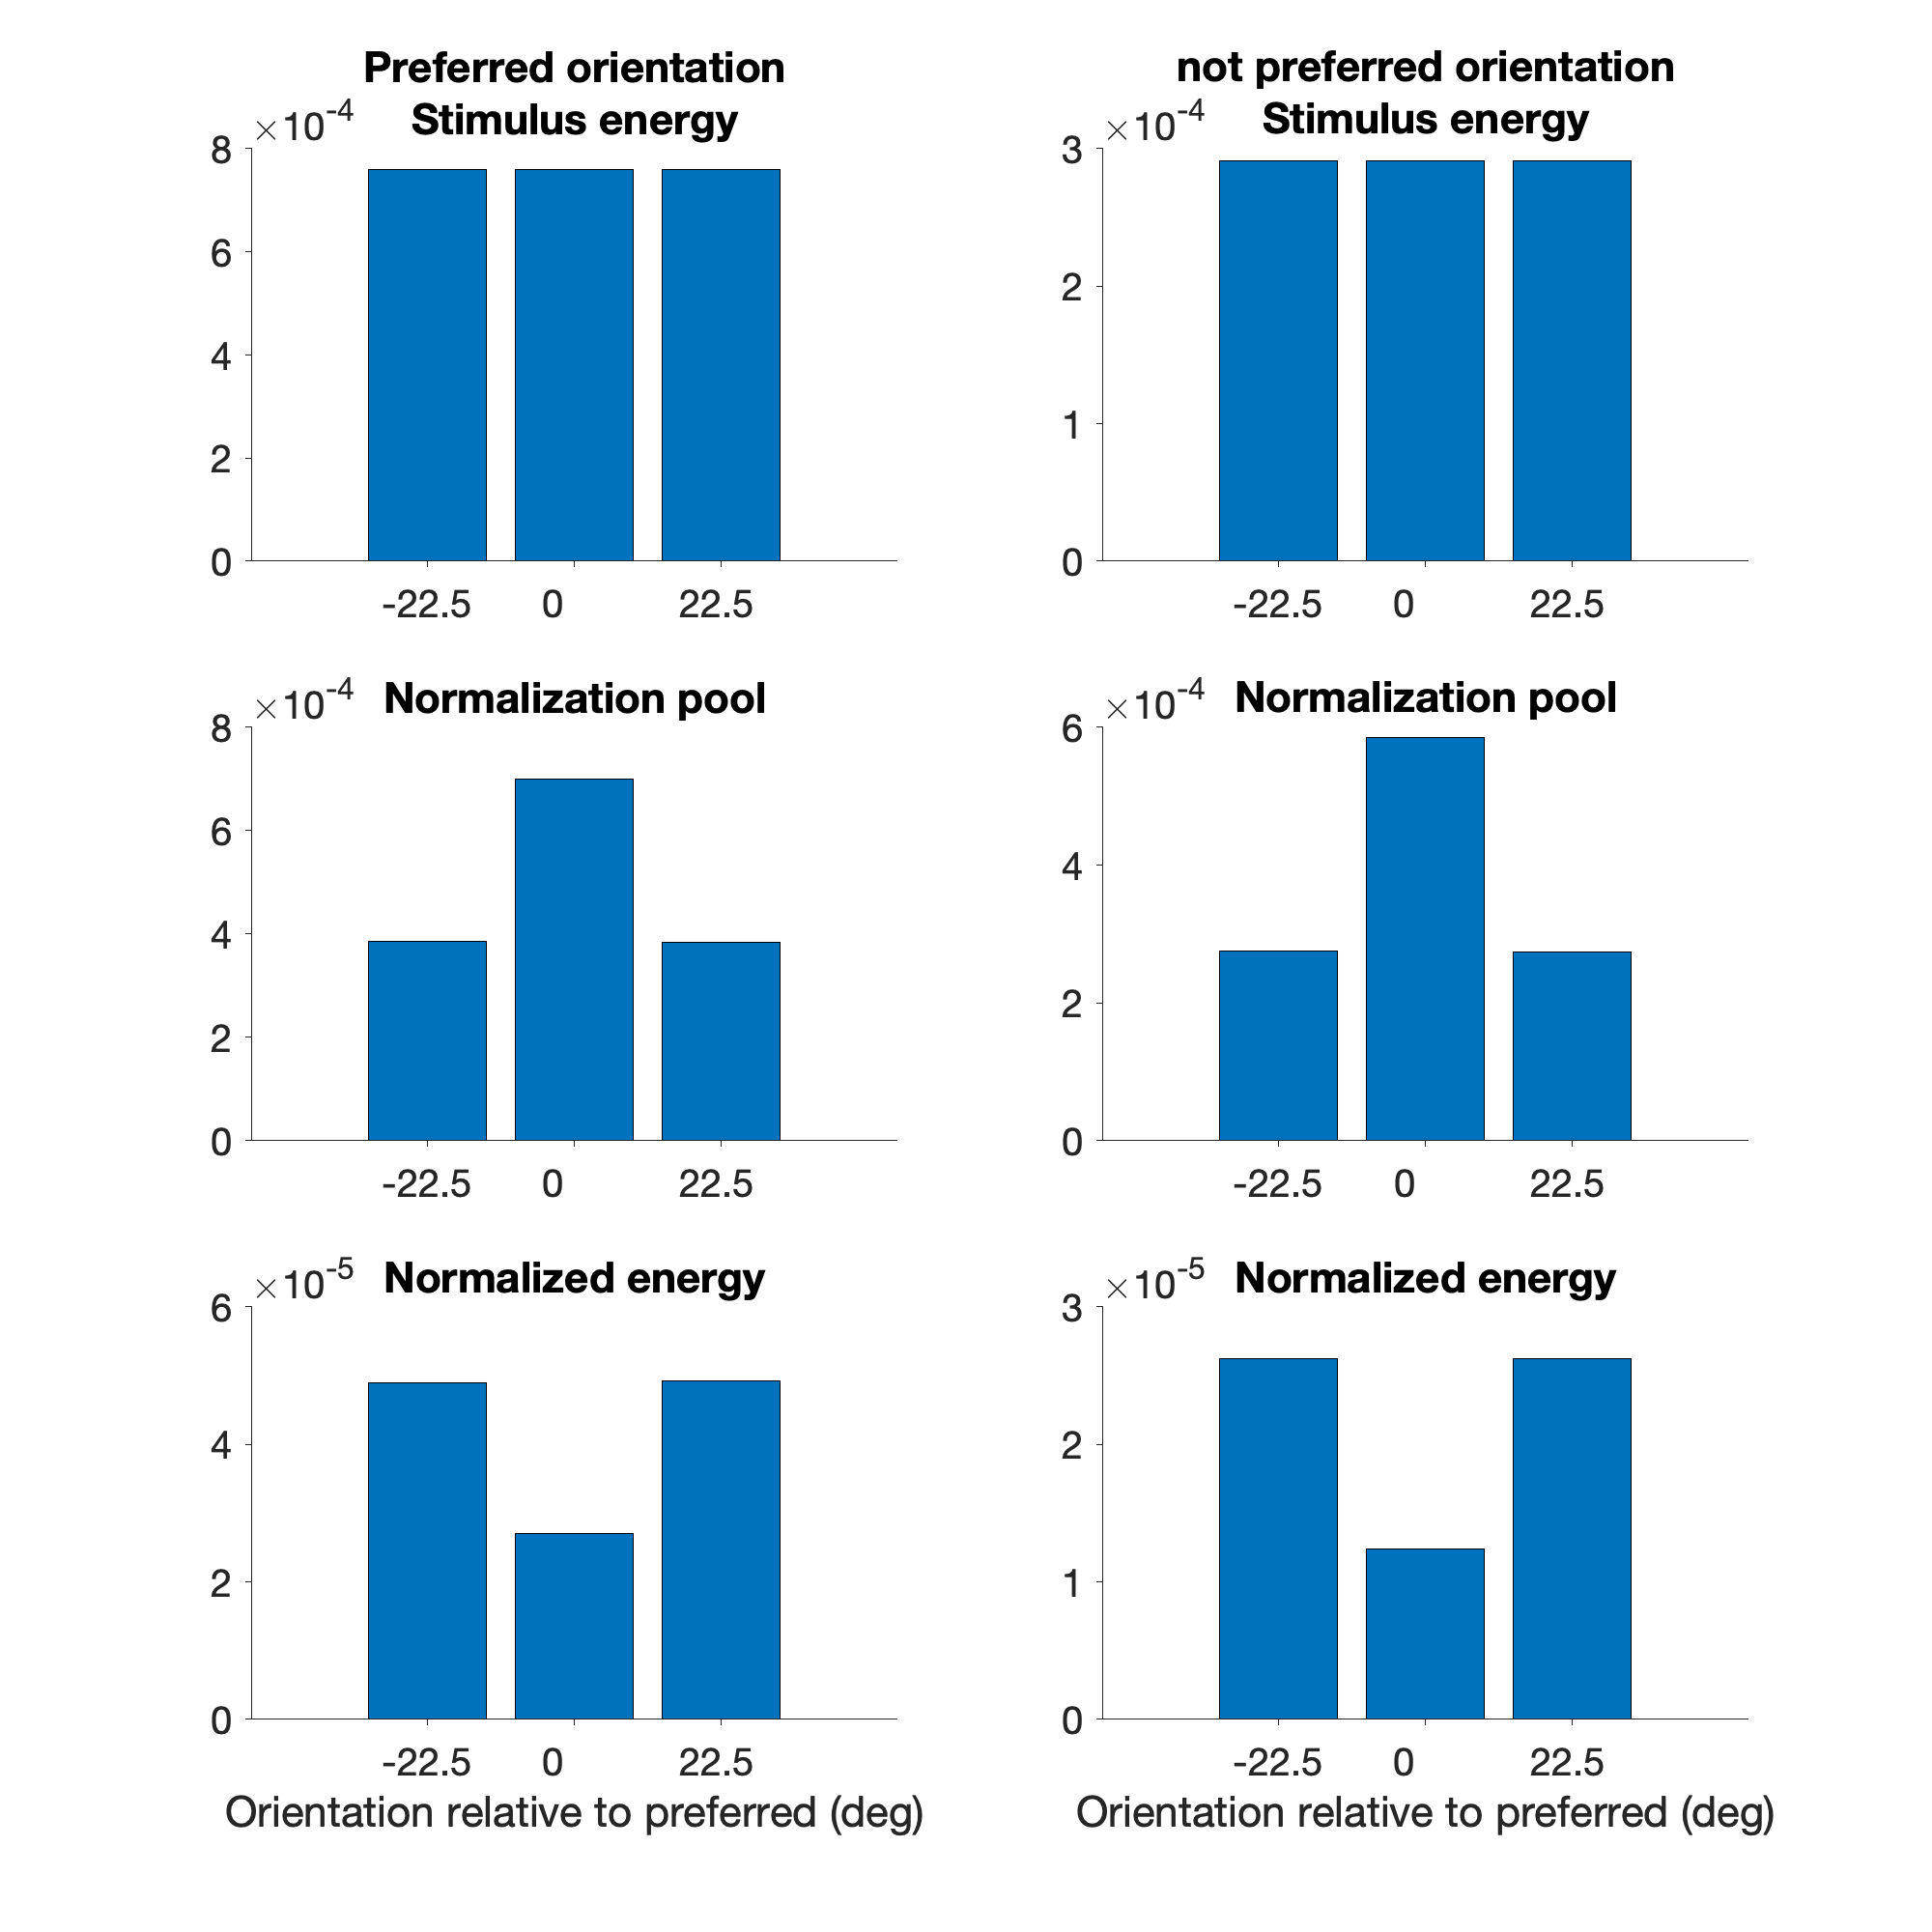

% Stimulus energy for vertical orientation tuning:
tmpE = squeeze(surr_E(:, :, 1, :, :));

% Normalization pool for vertical orientation tuning:
tmpZ = squeeze(Z(:, :, 1, :, :));

% Normalize
tmpD = tmpE ./ (sig+ tmpZ);

% Summarize over space:
tmpE = squeeze(mean((tmpE .* w), [1 2]));
tmpZ = squeeze(mean((tmpZ .* w), [1 2]));
tmpD = squeeze(mean((tmpD .* w), [1 2]));

figure('Position', [10 10 1000 1000])
subplot(3,2,1)
bar(-22.5:22.5:22.5, [tmpE(8,1) tmpE(1:2,1)'])
box off;
title([{'Preferred orientation'};{'Stimulus energy'}])
set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')

subplot(3,2,3)
bar(-22.5:22.5:22.5, [tmpZ(8,1) tmpZ(1:2,1)'])
box off;
title('Normalization pool')
set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')

subplot(3,2,5)
bar(-22.5:22.5:22.5, [tmpD(8,1) tmpD(1:2,1)'])
box off;
title('Normalized energy')
set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')
xlabel('Orientation relative to preferred (deg)')

subplot(3,2,2)
bar(-22.5:22.5:22.5, [tmpE(8,2) tmpE(1:2,2)'])
box off;
title([{'not preferred orientation'};{'Stimulus energy'}])
set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')

subplot(3,2,4)
bar(-22.5:22.5:22.5, [tmpZ(8,2) tmpZ(1:2,2)'])
box off;
title('Normalization pool')
set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')

subplot(3,2,6)
bar(-22.5:22.5:22.5, [tmpD(8,2) tmpD(1:2,2)'])
box off;
title('Normalized energy')

set(gca, 'Xtick', [-22.5 0 22.5], 'XtickLabel', [-22.5 0 22.5], 'FontSize', 20, 'TickDir', 'out')
xlabel('Orientation relative to preferred (deg)')

## Normalized center responses

whichCent = 1;
% X x Y x Orient x SurroundDiff
Z = NaN(size(tune_E,1), size(tune_E,2), size(tune_E,3), size(tune_E,4));
for ep = 1:nOri
    % energy: x, y, neuron orient, center Orient
    E = tune_E(:, :, :, ep);

    Z_thetas = NaN(size(E));
    
    for theta1 = 1:nOri
        Ztheta1 = 0;
        for theta2 = 1:nOri
            kernel_2d = F(:,:,theta1,theta2);
            image_theta = E(:,:,theta2);
            z_theta = conv2(image_theta, kernel_2d, 'same');
            Ztheta1 = Ztheta1 + z_theta;
        end
        Z_thetas(:,:,theta1) = Ztheta1;
    end
    
    Z(:,:,:,ep) = Z_thetas;
end

% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = squeeze(tune_E(:,:,:,:)) ./ (sig + Z);

% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(w .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Response to all center orientations for a neuron tuned to whichCent
r_center = s(:,whichCent);
 


#### Get the curves

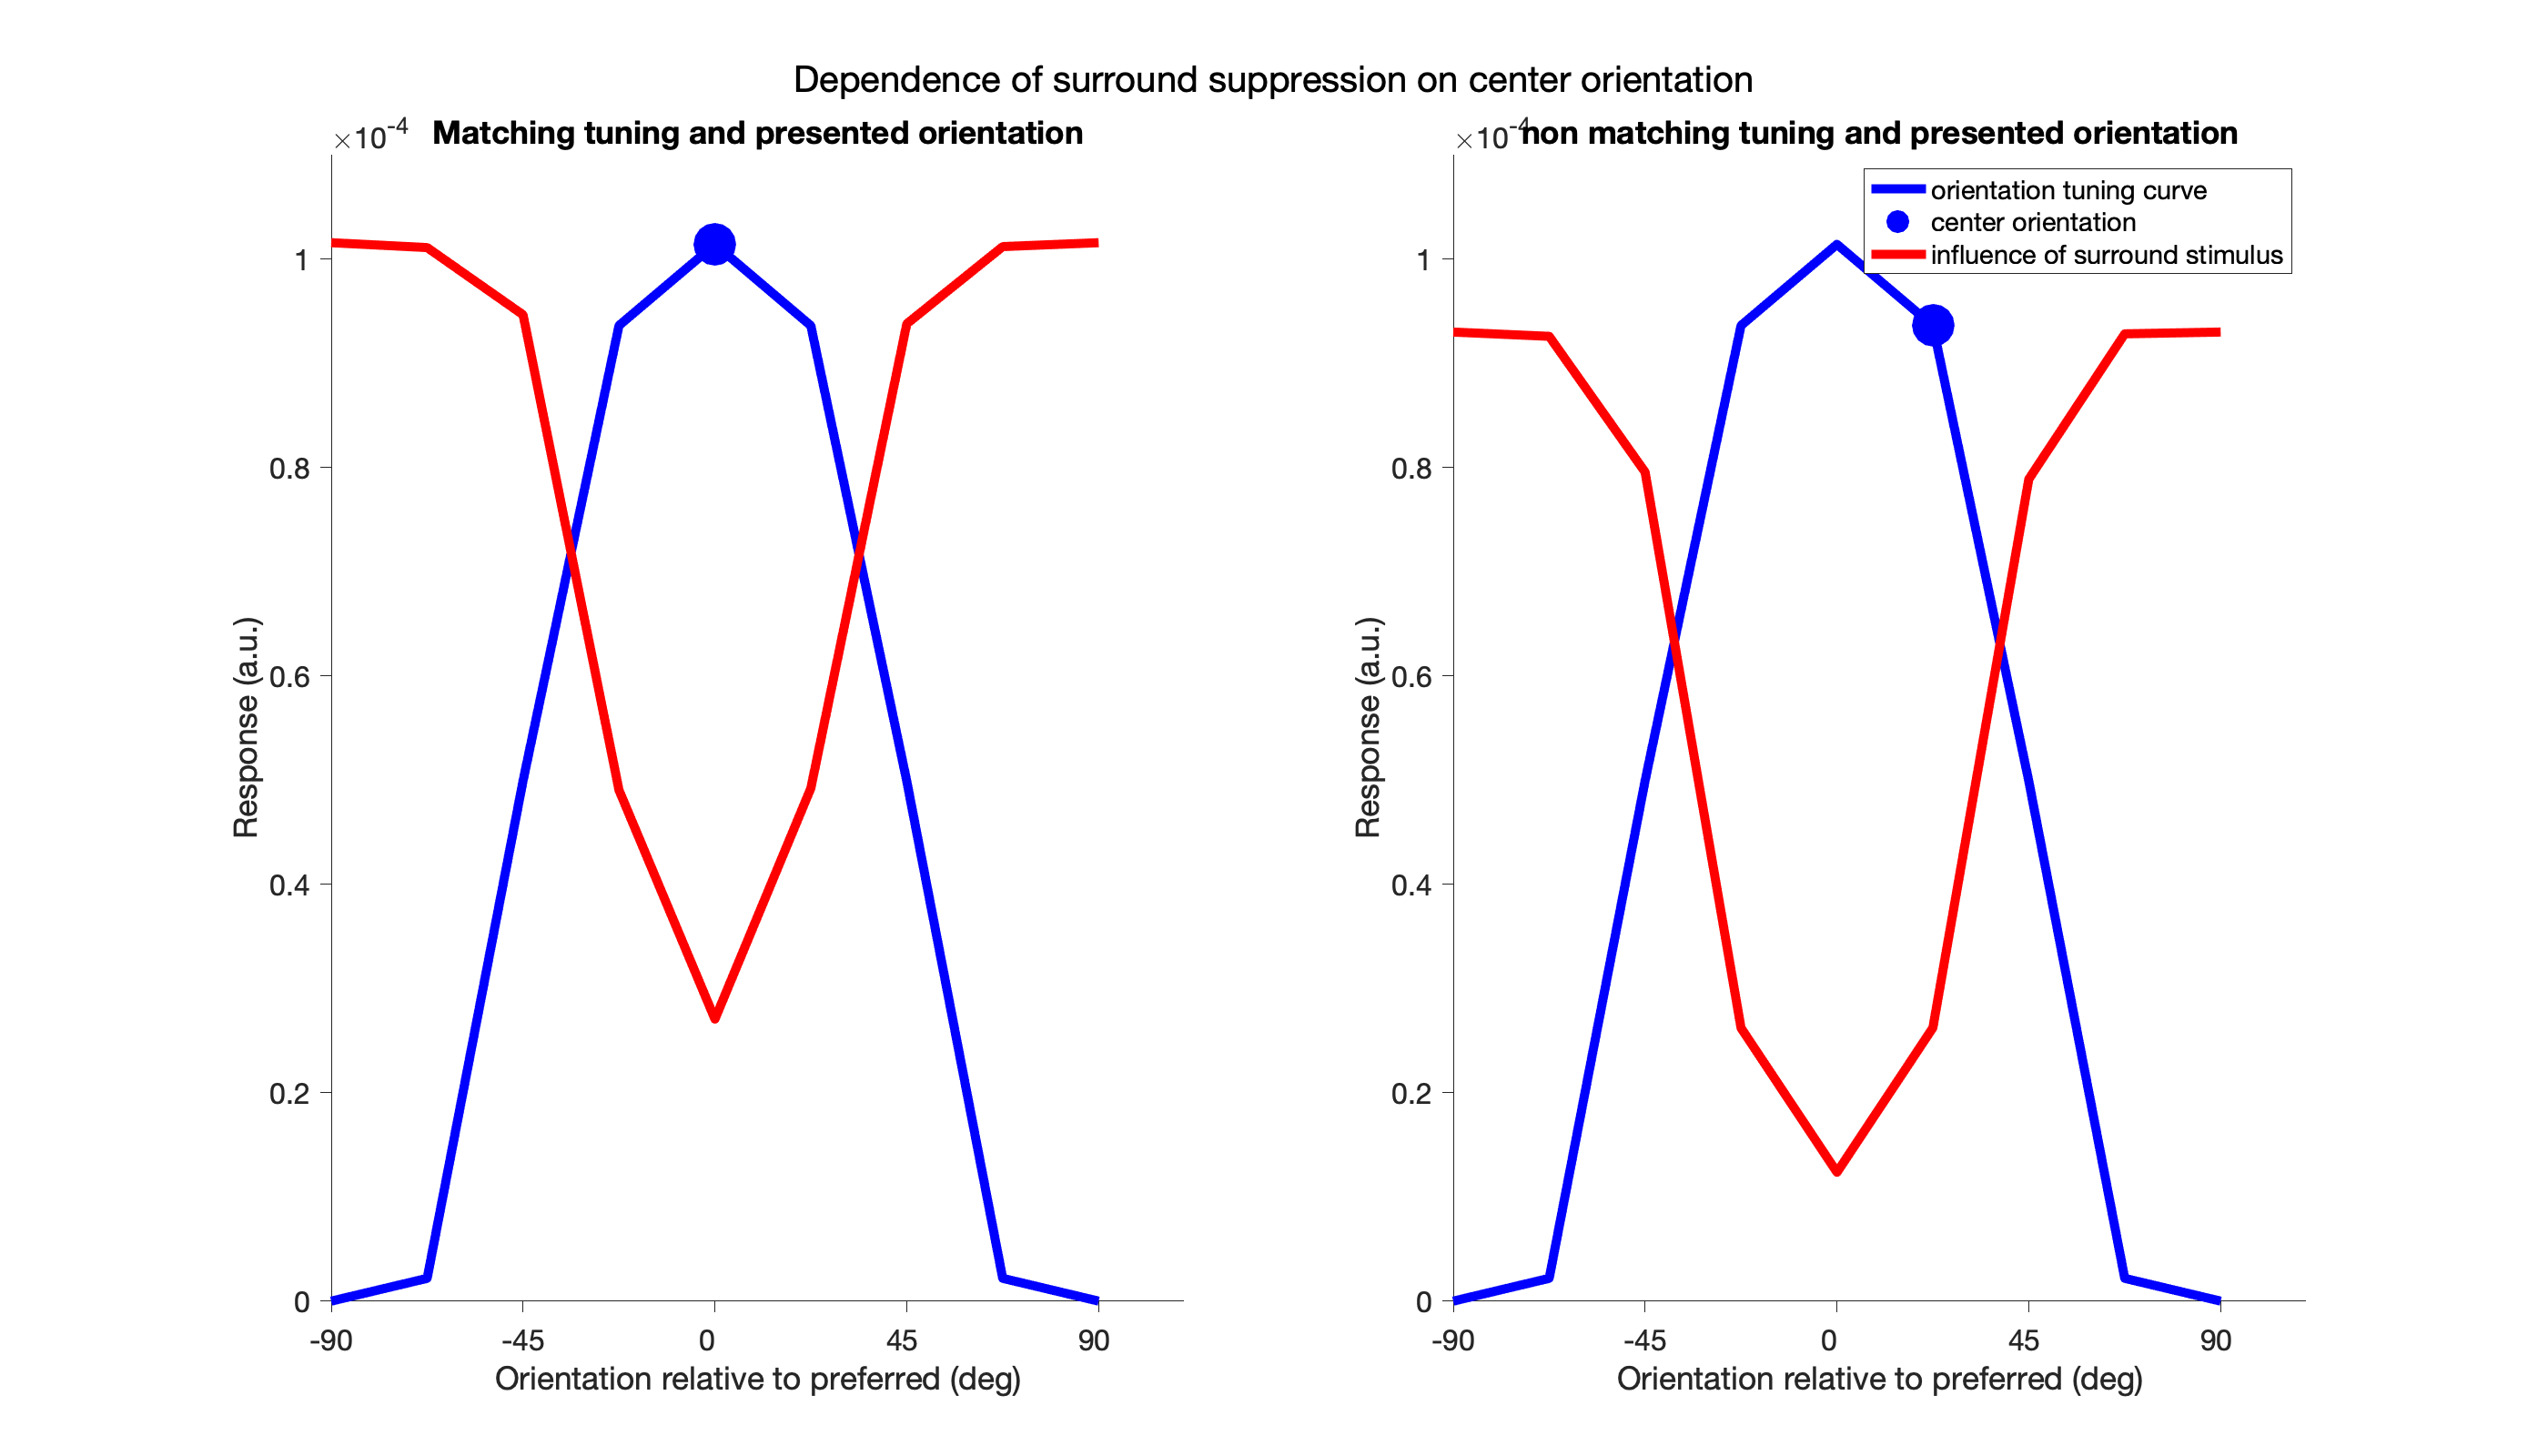


tune_curve      = zeros(nOri,1);
tune_curve(1:4,:) = r_center(5:8,:);
tune_curve(5:8,:) = r_center(1:4,:);

supp_curve      = zeros(nOri,nCentOrient);
supp_curve(1:4,:) = r_surround(5:8,:);
supp_curve(5:8,:) = r_surround(1:4,:);

tune_curve2 = [tune_curve; tune_curve(1)];
supp_curve2 = [supp_curve; supp_curve(1,:)];

ybounds = [0 ceil(max(supp_curve2(:)*100000))/100000];
fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800], 'color', [1 1 1]);
subplot(1,2,1)
plot(rad2deg([orientations pi]), tune_curve2, 'b', 'LineWidth', 5)
hold on
plot(rad2deg(orientations(5)), tune_curve2(5), 'b.', 'MarkerSize', 80)
plot(rad2deg([orientations pi]), supp_curve2(:,1),'r', 'LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 16, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation', 'Fontsize', 16)


subplot(1,2,2)
plot(rad2deg([orientations pi]), tune_curve2,'b','LineWidth', 5)
hold on
plot(rad2deg(orientations(6)), tune_curve2(6), 'b.', 'MarkerSize', 80)
plot(rad2deg([orientations pi]), supp_curve2(:,2),'r','LineWidth', 5)
box off; ylim(ybounds)
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 16, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation', 'Fontsize', 16)
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus')

sgtitle('Orientation tuned suppression model predictions', 'FontSize', 20);

% yline(prefer_res, '-.k', 'LineWidth', 3)

#### NOA model

% example for NOA model
params = [1, 1];
sig = params(1); alpha = params(2);

for whichCent = 1:nCentOrient
    % energy: % x, y, orient_channnel, surrOri, centOri
    E = squeeze(surr_E(:,:,:,:,whichCent));
    % get normalizer: Z = const 
    E_ori = squeeze(mean(E, [1, 2]));
    Z = std(E_ori, 1);
    % normalized energy: D(θ,surrOri) = E(θ,surrOri) ./ (sig + Z)
    d = squeeze(mean(E .* w, [1, 2])) ./ repmat((sig + Z), [nOri, 1]);
    % add exponential
    s = d.^alpha;
    r_surrNOA(:,whichCent) = s(1,:); 
end



% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,1));
% get normalizer: Z = const
E_ori = squeeze(mean(E, [1, 2]));
Z = std(E_ori, 1);
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
d = squeeze(mean(E .* w, [1, 2])) ./ (sig + Z);
% add exponential
s = d.^alpha;
r_centNOA = s; 

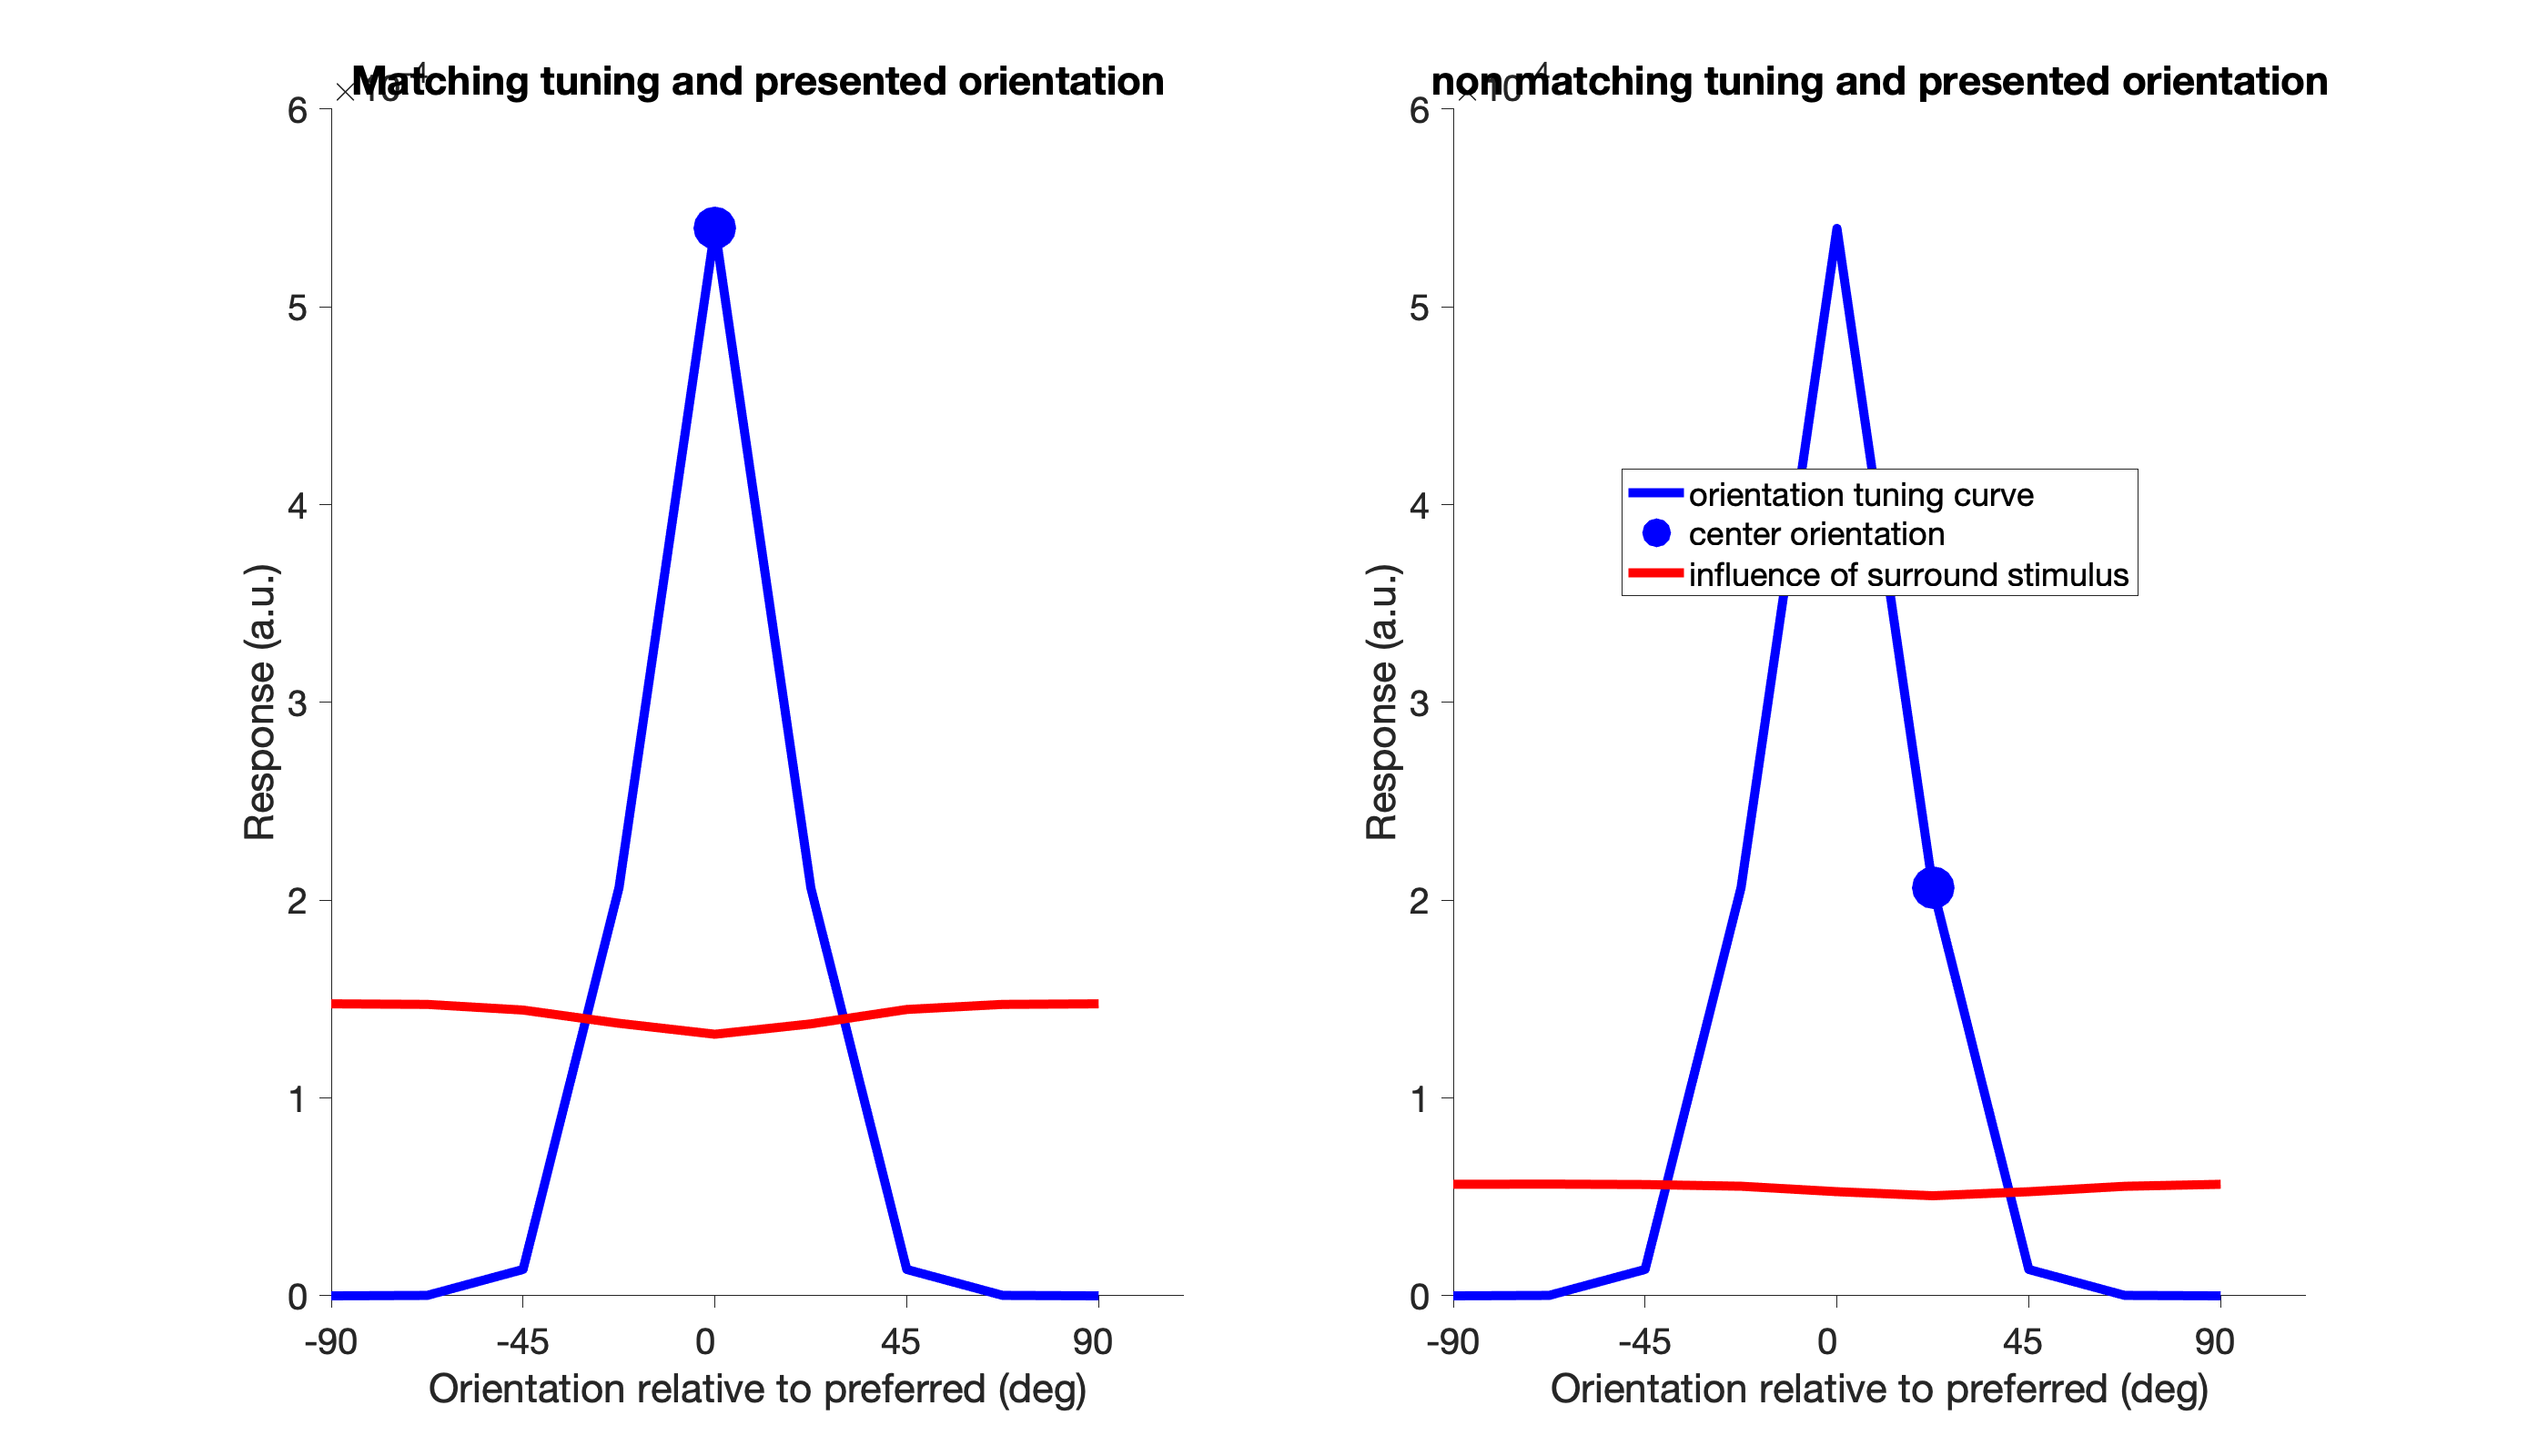

%
tune_curve(1:4) = r_centNOA(5:8);
tune_curve(5:8) = r_centNOA(1:4);

supp_curve(1:4,:) = r_surrNOA(5:8,:);
supp_curve(5:8,:) = r_surrNOA(1:4,:);

tune_curve3 = [tune_curve; tune_curve(1)];
supp_curve3 = [supp_curve; supp_curve(1,:)];

fig = figure('Renderer', 'painters', 'Position', [10 10 1400 800]);
subplot(1,2,1)
plot(0:22.5:180, tune_curve3, 'b', 'LineWidth', 5)
hold on
plot(90, tune_curve3(5), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve3(:,1),'r', 'LineWidth', 5)
box off; 
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('Matching tuning and presented orientation')

subplot(1,2,2)
plot(0:22.5:180, tune_curve3,'b','LineWidth', 5)
hold on
plot(112.5, tune_curve3(6), 'b.', 'MarkerSize', 80)
plot(0:22.5:180, supp_curve3(:,2),'r','LineWidth', 5)
box off; 
set(gca, 'Xtick', [0 45 90 135 180], 'XtickLabel', [-90 -45 0 45 90], 'FontSize', 20, 'TickDir', 'out')
ylabel('Response (a.u.)'); xlabel('Orientation relative to preferred (deg)')
title('non matching tuning and presented orientation')
legend('orientation tuning curve', 'center orientation', 'influence of surround stimulus', 'Location',"Best")

han=axes(fig,'visible','off');
title(han,'Dependence of surround suppression on center orientation','FontSize', 20);

sgtitle('NOA model predictions', 'FontSize', 20);
